# Specify Conditional Variance Model for Exchange Rates

This example shows how to specify a conditional variance model for daily Deutschmark/British pound foreign exchange rates observed from January 1984 to December 1991. 

## Load the Data.

Load the exchange rate data included with the toolbox. 

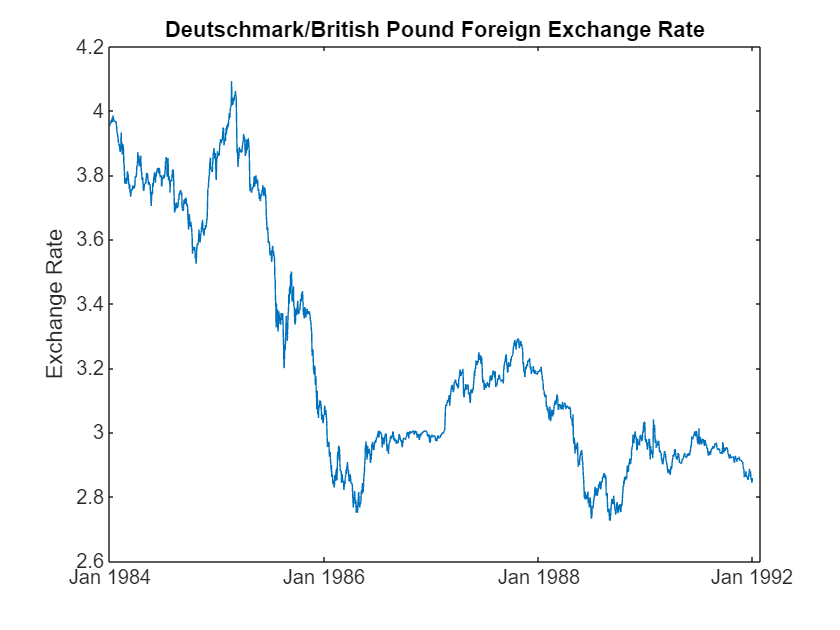

load Data_MarkPound
y = Data;
T = length(y);

figure
plot(y)
h = gca;
h.XTick = [1 659 1318 1975];
h.XTickLabel = {'Jan 1984','Jan 1986','Jan 1988',...
     'Jan 1992'};
ylabel 'Exchange Rate';
title 'Deutschmark/British Pound Foreign Exchange Rate';

The exchange rate looks nonstationary (it does not appear to fluctuate around a fixed level). 

## Calculate the Returns.

Convert the series to returns. This results in the loss of the first observation. 

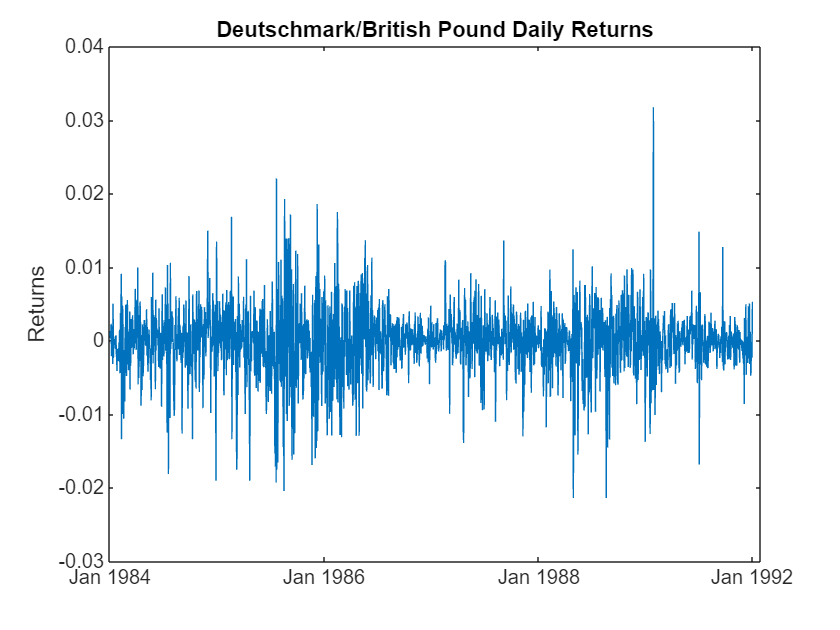

r = price2ret(y);

figure
plot(2:T,r)
h2 = gca;
h2.XTick = [1 659 1318 1975];
h2.XTickLabel = {'Jan 1984','Jan 1986','Jan 1988',...
     'Jan 1992'};
ylabel 'Returns';
title 'Deutschmark/British Pound Daily Returns';

The returns series fluctuates around a common level, but exhibits volatility clustering. Large changes in the returns tend to cluster together, and small changes tend to cluster together. That is, the series exhibits conditional heteroscedasticity.

The returns are of relatively high frequency. Therefore, the daily changes can be small. For numerical stability, it is good practice to scale such data. In this case, scale the returns to percentage returns.

r = 100*r;

## Check for Autocorrelation.

Check the returns series for autocorrelation. Plot the sample ACF and PACF, and conduct a Ljung-Box Q-test. 

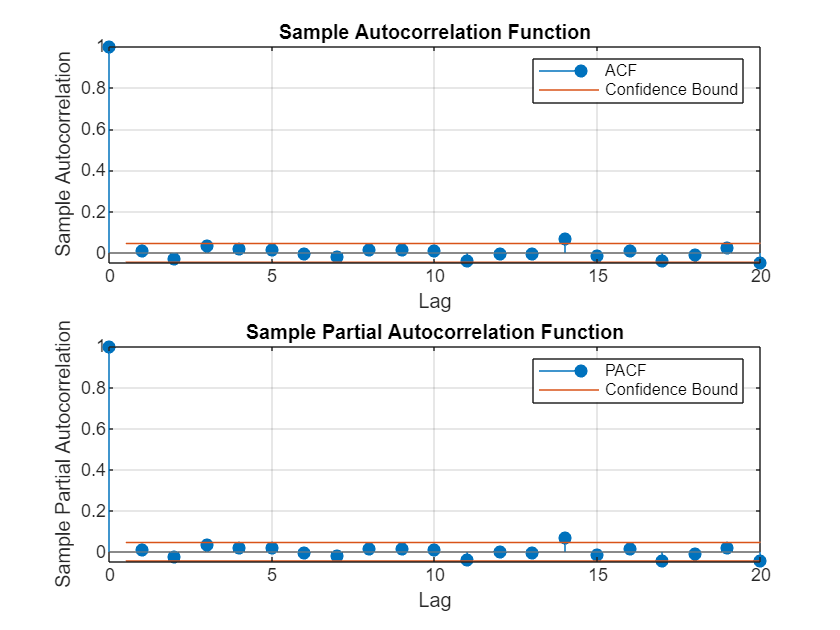

figure
subplot(2,1,1)
autocorr(r)
subplot(2,1,2)
parcorr(r)


[h,p] = lbqtest(r,'Lags',[5 10 15])

h = 1×3 logical array
   0   0   0


p =     0.3982    0.7278    0.2109


The sample ACF and PACF show virtually no significant autocorrelation. The Ljung-Box Q-test null hypothesis that all autocorrelations up to the tested lags are zero is not rejected for tests at lags 5, 10, and 15. This suggests that a conditional mean model is not needed for this returns series. 

## Check for Conditional Heteroscedasticity.

Check the return series for conditional heteroscedasticity. Plot the sample ACF and PACF of the squared returns series (after centering). Conduct Engle's ARCH test with a two-lag ARCH model alternative. 

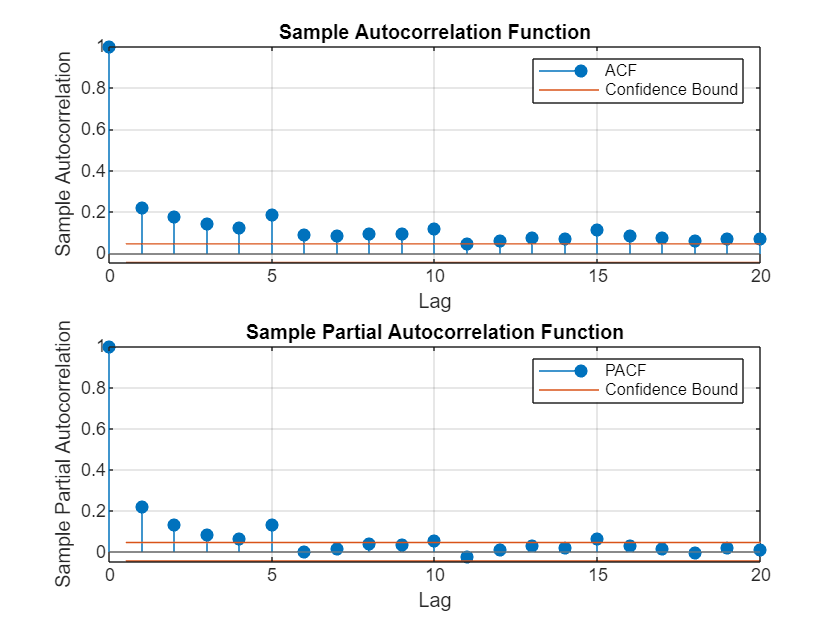

figure
subplot(2,1,1)
autocorr((r-mean(r)).^2)
subplot(2,1,2)
parcorr((r-mean(r)).^2)


[h,p] = archtest(r-mean(r),'Lags',2)

h = logical
   1


p = 0

The sample ACF and PACF of the squared returns show significant autocorrelation. This suggests a GARCH model with lagged variances and lagged squared innovations might be appropriate for modeling this series. Engle's ARCH test rejects the null hypothesis (`h = 1`) of no ARCH effects in favor of the alternative ARCH model with two lagged squared innovations. An ARCH model with two lagged innovations is locally equivalent to a GARCH(1,1) model. 

## Specify a GARCH(1,1) Model.

Based on the autocorrelation and conditional heteroscedasticity specification testing, specify the GARCH(1,1) model with a mean offset: 


$$y_t = \mu + \varepsilon_t,$$


with $\varepsilon_t = \sigma_t z_t$ and 


$$\sigma _t^2 = \kappa  + {\gamma _1}\sigma _{t - 1}^2 + {\alpha _1}\varepsilon _{t - 1}^2.$$


Assume a Gaussian innovation distribution. 

Mdl = garch('Offset',NaN,'GARCHLags',1,'ARCHLags',1)

Mdl =   garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: NaN
           GARCH: {NaN} at lag [1]
            ARCH: {NaN} at lag [1]
          Offset: NaN

The created model, `Mdl`, has `NaN` values for all unknown parameters in the specified GARCH(1,1) model. 

You can pass the GARCH model `Mdl` and `r` into `estimate` to estimate the parameters.

**Estimate Parameters of the Model**

Mdl = estimate(Mdl,r)

 
    GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant      0.010761       0.001323         8.1342     4.1454e-16
    GARCH{1}       0.80597        0.01656         48.669              0
    ARCH{1}        0.15313       0.013974         10.959     6.0379e-28
    Offset      -0.0061904      0.0084336       -0.73402        0.46294



Mdl =   garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: 0.0107613
           GARCH: {0.805974} at lag [1]
            ARCH: {0.153134} at lag [1]
          Offset: -0.00619042

**Forecast Volatility**

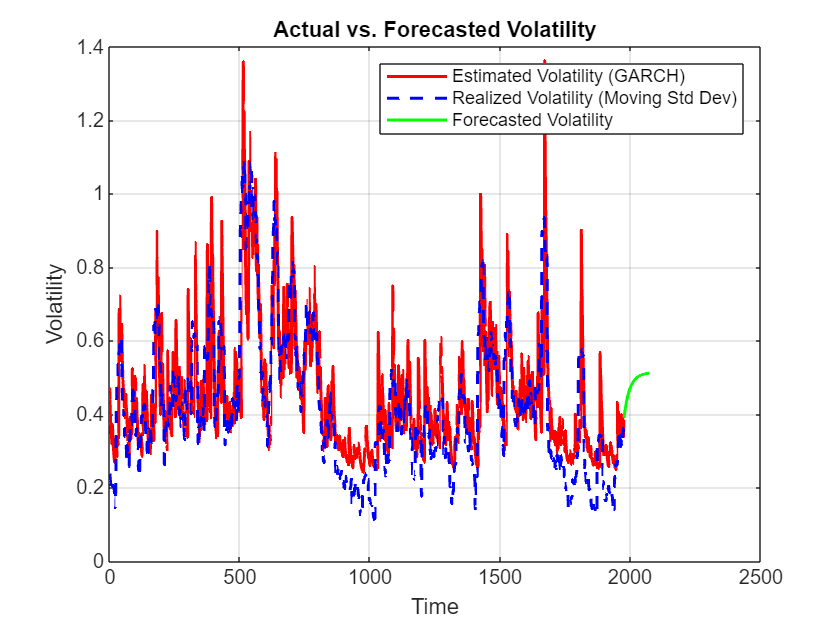

%% Forecast Volatility
% Forecast volatility for a specified horizon
v = infer(Mdl, r);
forecastHorizon = 100; % Forecast 100 days ahead
vF = forecast(Mdl, forecastHorizon, 'Y0', r);

% Extend the inferred variances to include the forecasted variances
v = [v; vF];

%% Compute Realized Volatility
% Compute realized volatility as moving standard deviation
window_size = 22; % 22 days (approximately one month)
realized_volatility = movstd(r, window_size);

% Extend the time vector to include forecast horizon
extendedT = (1:T+forecastHorizon)';

%% Plot the actual vs. forecasted volatility
figure;
plot(1:T, sqrt(v(1:T)), 'r-', 'LineWidth', 1.5);
hold on;
plot(1:T-1, realized_volatility, 'b--', 'LineWidth', 1.5);
plot(T+1:T+forecastHorizon-1, sqrt(v(T+1:end)), 'g-', 'LineWidth', 1.5);
title('Actual vs. Forecasted Volatility');
xlabel('Time');
ylabel('Volatility');
legend('Estimated Volatility (GARCH)', 'Realized Volatility (Moving Std Dev)', 'Forecasted Volatility');
grid on;
hold off;